%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader toehold length on DNA/DNA TMSD kinetics
%including spontaneous incumbent dissociation 

b = 20 %define branch migration domain length 

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

ana_k_eff = zeros(1,15)

ana_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through invader toehold lengths 
for g = 1:15
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    
    if g == 1
        %create arrays of forward and reverse transition rates
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
        %define spontaneous incumbent dissociation rates
        Koff = [0];
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0, 0])
        
    else
        %create arrays of forward and reverse transition rates
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
        %define spontaneous incumbent dissociation rates
        Koff = [0];
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    first_pass_time (g) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
    ana_k_eff (g) = 1/(first_pass_time (g)*(5*10^-8)); %calculate effective rate constant
    prob_unbound (g) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate probability of being in unbound state
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+04 *

    0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002    0.0001         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954


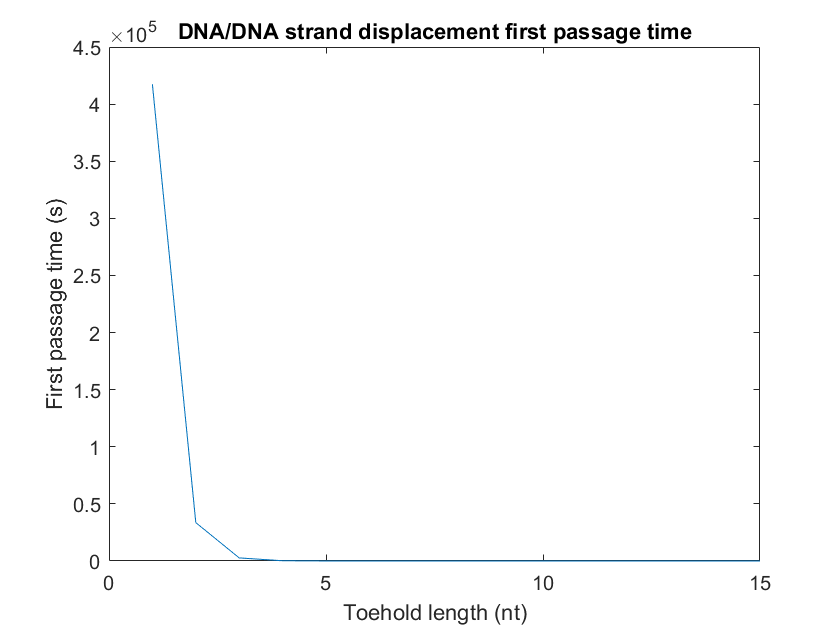

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

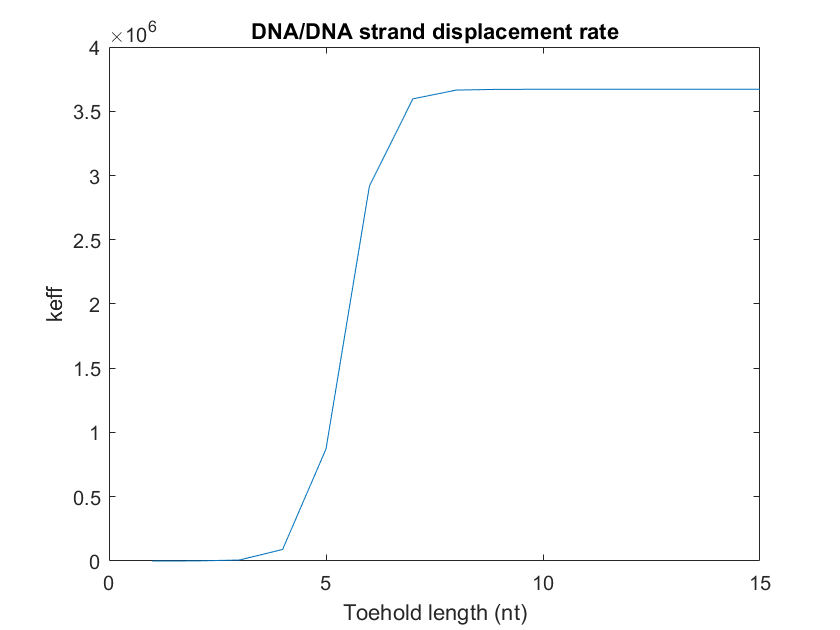


plot(1:15, ana_k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')


ax = gca;
plot(1:15, log10(ana_k_eff),'Color', '[0.6350, 0.0780, 0.1840]', 'linewidth', 2)
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


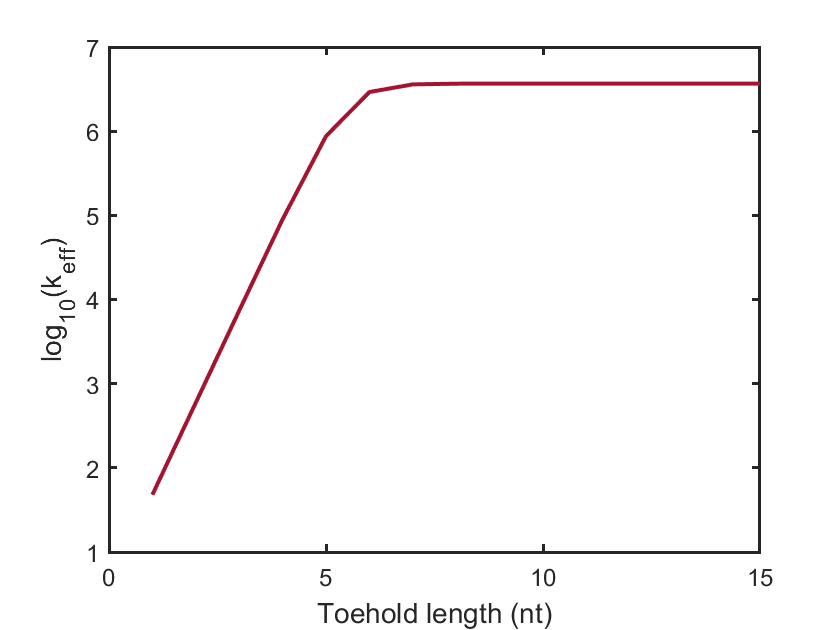

xlabel('Toehold length (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)

%title('DNA/DNA strand displacement rate')  
